# 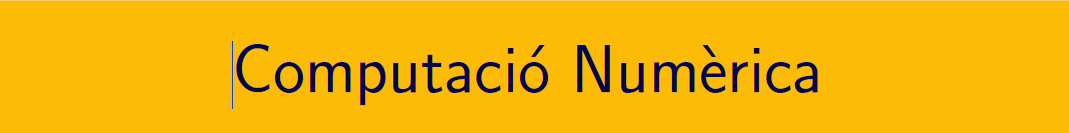

`================================================================================`

# Pràctica 12. Equacions diferencials ordinàries (III).

`Document preparat per M. Àngela Grau Gotés - 23 de maig de 2022`

## Mètodes multipas

## `Exercici  `$y^{\prime}(t)=y(t)+t^2\,,\quad y(0)=1,\quad 0\leq t\leq 1\,.$

`Solució analítica`

clearvars
syms y(t)
eqn = diff(y,t) == y+t^2;
cond = y(0) == 1;
ySol(t) = dsolve(eqn,cond)

`La solució es pot respresentar a l'interval [0,1]`

fplot(ySol,[0,1])

## `Solucions aproximades numèricament O(h^4)`

- `Mètode RK4`

a = 0; alpha = 1;    % y(a) = alpha
b = 1;                % y(b) = ...
f = @(t,y)(y+t.^2);



- `Mètode Adams-Moulton`

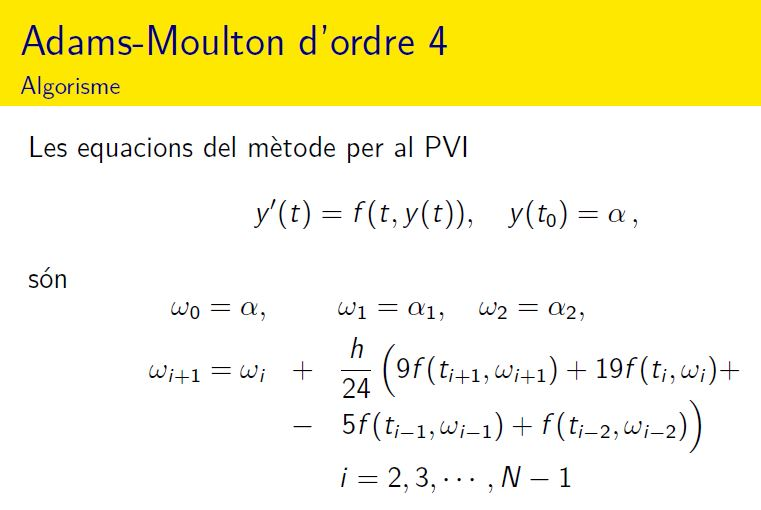

- `Mètode Adams-Moulton, els primers calculats exactament`

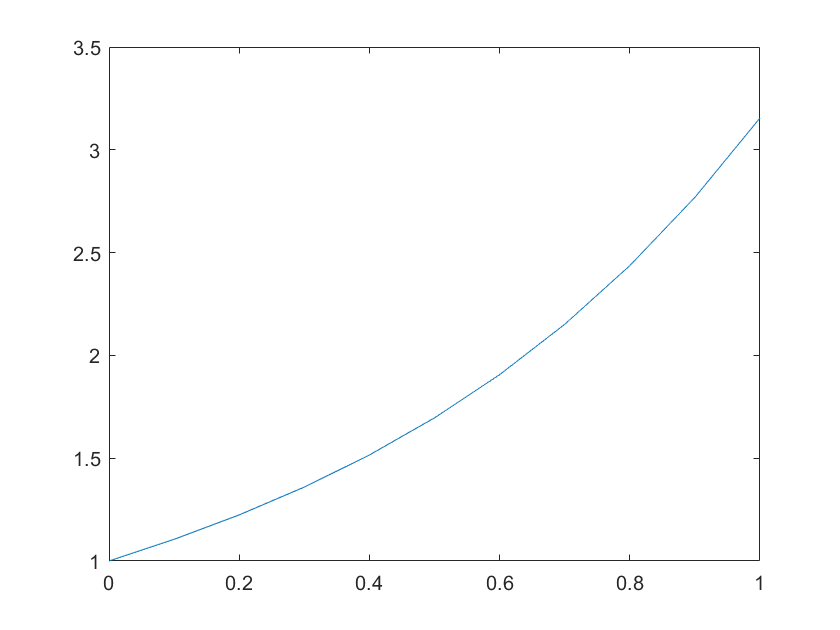

% Mètode de  Adams-Basforth
% iniciem per valor exacte
h= 0.1;
t=[a:h:b];
N=length(t);
w(1) = alpha;
w(2) = ySol(t(2));
w(3) = ySol(t(3));
w(4) = ySol(t(4));

for i=3:N-1
    a1 = 19*f(t(i),w(i)); 
    a2 = -5*f(t(i-1),w(i-1));
    a3 =    f(t(i-2),w(i-2));
    F = @(z)(z-w(i)-h/24*(9*f(t(i+1),z)+a1+a2+a3));
    w(i+1) = fzero(F,w(i));
end

plot(t,w)

error_gl = double(abs(w(end)-ySol(b)))

error_gl = 1.5902e-05

wSol = w;
Y = double(ySol(t));
E = abs(Y-wSol);
disp(table(t',Y',wSol',E','VariableNames',{'t','Y','Y_AB','E_{local}'}))

     t       Y        Y_AB     E_{local} 
    ___    ______    ______    __________

      0         1         1             0
    0.1    1.1055    1.1055             0
    0.2    1.2242    1.2242             0
    0.3    1.3596    1.3596    9.7692e-07
    0.4    1.5155    1.5155     2.175e-06
    0.5    1.6962    1.6962    3.6107e-06
    0.6    1.9064    1.9064    5.3242e-06
    0.7    2.1513    2.1513    7.3583e-06
    0.8    2.4366    2.4366    9.7612e-06
    0.9    2.7688    2.7688    1.2588e-05
      1    3.1548    3.1549    1.5902e-05



- `Mètode Adams-Moulton, els primers calculats per RK4`

% Mètode de  Adams-Basforth
% iniciem per RK4
wrk4  = RK4( f,a,t(4),h,alpha )

wrk4 =     1.0000    1.1055    1.2242    1.3596


w(1) = alpha;
w(2) = wrk4(2);
w(3) = wrk4(3);
w(4) = wrk4(4);


for i=3:N-1
    a1 = 19*f(t(i),w(i)); 
    a2 = -5*f(t(i-1),w(i-1));
    a3 =    f(t(i-2),w(i-2));
    F = @(z)(z-w(i)-h/24*(9*f(t(i+1),z)+a1+a2+a3));
    w(i+1) = fzero(F,w(i));
end

plot(t,w)

error_gl = double(abs(w(end)-ySol(b)))

error_gl = 1.5626e-05

wSol = w;
Y = double(ySol(t));
E = abs(Y-wSol);
disp(table(t',Y',wSol',E','VariableNames',{'t','Y','Y_AB','E_{local}'}))

     t       Y        Y_AB     E_{local} 
    ___    ______    ______    __________

      0         1         1             0
    0.1    1.1055    1.1055    4.5894e-08
    0.2    1.2242    1.2242    1.2335e-07
    0.3    1.3596    1.3596    8.3961e-07
    0.4    1.5155    1.5155    2.0235e-06
    0.5    1.6962    1.6962    3.4433e-06
    0.6    1.9064    1.9064    5.1392e-06
    0.7    2.1513    2.1513    7.1538e-06
    0.8    2.4366    2.4366    9.5352e-06
    0.9    2.7688    2.7688    1.2339e-05
      1    3.1548    3.1549    1.5626e-05



function  w  = RK4( f,a,b,h,alpha )
% Mètode RK4
    t=[a:h:b];
    N=length(t);
    w(1)=alpha;
    for i=1:N-1
        k1=h*f(t(i),w(i));
        k2=h*f(t(i)+h/2,w(i)+k1/2);
        k3=h*f(t(i)+h/2,w(i)+k2/2);
        k4=h*f(t(i+1),w(i)+k3);
        w(i+1)=w(i)+(k1+2*k2+2*k3+k4)/6;
    end
end
%---------------------------------------
function [ w ] = Euler( f,a,b,h,alpha )
% Mètode d'Euler
t=[a:h:b];
N=length(t);
w(1)=alpha;
    for i=1:N-1
        w(i+1)=w(i)+h*f(t(i),w(i));
    end
end
%---------------------------------------